## **Face ricognition using Siamese Network**

A Siamese network is a type of deep learning network that uses two or more identical subnetworks that have the same architecture and share the same parameters and weights. Siamese networks are typically used in tasks that involve finding the relationship between two comparable things. Some common applications for Siamese networks include facial recognition, signature verification, or paraphrase identification. Siamese networks perform well in these tasks because their shared weights mean there are fewer parameters to learn during training and they can produce good results with a relatively small amount of training data.

Siamese networks are particularly useful in cases where there are large numbers of classes with small numbers of observations of each. In such cases, there is not enough data to train a deep convolutional neural network to classify images into these classes. Instead, the Siamese network can determine if two images are in the same class.

close all;
clear all;
clc;

## The Database of Faces

Our Database of Faces, (formerly 'The ORL Database of Faces'), contains a set of face images taken between April 1992 and April 1994 at the lab. The database was used in the context of a face recognition project carried out in collaboration with the Speech, Vision and Robotics Group of the Cambridge University Engineering Department.

There are ten different images of each of 40 distinct subjects. For some subjects, the images were taken at different times, varying the lighting, facial expressions (open / closed eyes, smiling / not smiling) and facial details (glasses / no glasses). All the images were taken against a dark homogeneous background with the subjects in an upright, frontal position (with tolerance for some side movement). A preview image of the Database of Faces is available.

The files are in PGM format, and can conveniently be viewed on UNIX (TM) systems using the 'xv' program. The size of each image is 92x112 pixels, with 256 grey levels per pixel. The images are organised in 40 directories (one for each subject), which have names of the form sX, where X indicates the subject number (between 1 and 40). In each of these directories, there are ten different images of that subject, which have names of the form Y.pgm, where Y is the image number for that subject (between 1 and 10).

80% images are used for training and the rest 20% images are used for validation.

The database can be retrieved from [http://www.cl.cam.ac.uk/Research/DTG/attarchive:pub/data/att_faces.zip](http://www.cl.cam.ac.uk/Research/DTG/attarchive:pub/data/att_faces.zip) as a ZIP file of similar size.

***Copyright © 2002 AT&T Laboratories Cambridge***

***Credit: ***[***https://www.cl.cam.ac.uk/research/dtg/attarchive/facedatabase.html***](https://www.cl.cam.ac.uk/research/dtg/attarchive/facedatabase.html)

Loading the training data as a image datastore using the `imageDatastore` function. Specify the labels manually by extracting the labels from the file names and setting the `Labels` property.

imdsTrain = imageDatastore("FaceData_Train",'IncludeSubfolders',true,...
    'LabelSource','none');

files = imdsTrain.Files;
parts = split(files,filesep);
labels = join(parts(:,(end-2):(end-1)),'_');
imdsTrain.Labels = categorical(labels);

Displaying a random selection of the images.

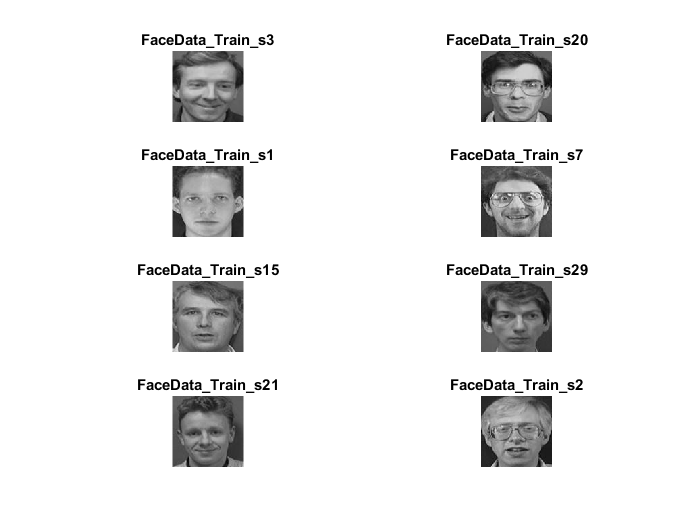

indexRandomImage = randperm(numel(imdsTrain.Files),8);

for i = 1:numel(indexRandomImage)
    subplot(4,2,i)
    imshow(readimage(imdsTrain,indexRandomImage(i)))
    title(imdsTrain.Labels(indexRandomImage(i)), "Interpreter","none");
end

**Create Pairs of Similar and Dissimilar Images**

To train the network, the data must be grouped into pairs of images that are either similar or dissimilar. Here, similar images are different images of the same person, which have the same label, while dissimilar images of different person have different labels. The function `getSiameseBatch` creates randomized pairs of similar or dissimilar images, `pairImage1` and `pairImage2`. The function also returns the label `pairLabel`, which identifies if the pair of images is similar or dissimilar to each other. Similar pairs of images have `pairLabel = 1`, while dissimilar pairs have `pairLabel = 0`.

As an example, creating a small representative set of five pairs of images

batchSize = 10;
[pairImage1,pairImage2,pairLabel] = getSiameseBatch(imdsTrain,batchSize);

Displaying the generated pairs of images.

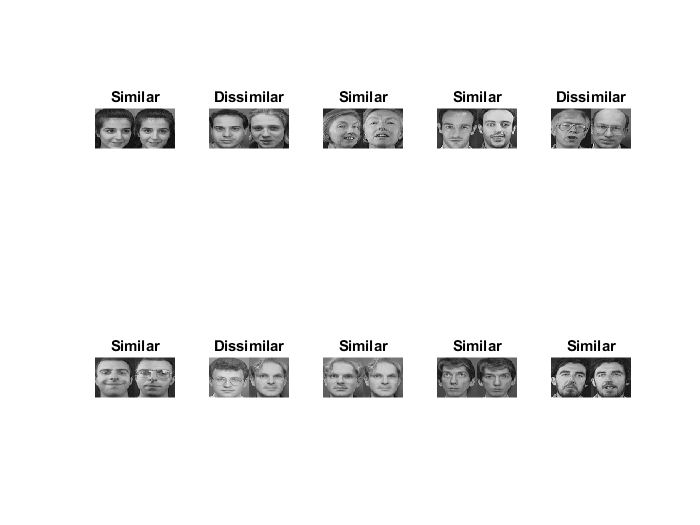

for i = 1:batchSize    
    if pairLabel(i) == 1
        s = "Similar";
    else
        s = "Dissimilar";
    end
    subplot(2,5,i)  
    photo1 = cast(pairImage1(:,:,1,i), 'uint8');
    photo2 = cast(pairImage2(:,:,1,i), 'uint8');
    imshow([photo1 photo2]);
    title(s)
end

The Siamese network architecture is illustrated in the following diagram.

To compare two images, each image is passed through one of two identical subnetworks that share weights. The subnetworks convert each 105-by-105-by-1 image to a 4096-dimensional feature vector. Images of the same class have similar 4096-dimensional representations. The output feature vectors from each subnetwork are combined through subtraction and the result is passed through a `fullyconnect` operation with a single output. A `sigmoid` operation converts this value to a probability between `0` and `1`, indicating the network's prediction of whether the images are similar or dissimilar. The binary cross-entropy loss between the network prediction and the true label is used to update the network during training.

In this example, the two identical subnetworks are defined as a `dlnetwork` object. The final `fullyconnect` and `sigmoid` operations are performed as functional operations on the subnetwork outputs.

Create the subnetwork as a series of layers that accepts 105-by-105-by-1 images and outputs a feature vector of size 4096.

For the `convolution2dLayer` objects, use the narrow normal distribution to initialize the weights and bias.

For the `maxPooling2dLayer` objects, set the stride to `2`.

For the final `fullyConnectedLayer` object, specify an output size of 4096 and use the narrow normal distribution to initialize the weights and bias.

layers = [
    imageInputLayer([105 105 1],'Name','input1','Normalization','none')
    convolution2dLayer(10,64,'Name','conv1','WeightsInitializer','narrow-normal','BiasInitializer','narrow-normal')
    reluLayer('Name','relu1')
    maxPooling2dLayer(2,'Stride',2,'Name','maxpool1')
    convolution2dLayer(7,128,'Name','conv2','WeightsInitializer','narrow-normal','BiasInitializer','narrow-normal')
    reluLayer('Name','relu2')
    maxPooling2dLayer(2,'Stride',2,'Name','maxpool2')
    convolution2dLayer(4,128,'Name','conv3','WeightsInitializer','narrow-normal','BiasInitializer','narrow-normal')
    reluLayer('Name','relu3')
    maxPooling2dLayer(2,'Stride',2,'Name','maxpool3')
    convolution2dLayer(5,256,'Name','conv4','WeightsInitializer','narrow-normal','BiasInitializer','narrow-normal')
    reluLayer('Name','relu4')
    fullyConnectedLayer(4096,'Name','fc1','WeightsInitializer','narrow-normal','BiasInitializer','narrow-normal')];

lgraph = layerGraph(layers)

lgraph =   LayerGraph with properties:

         Layers: [13×1 nnet.cnn.layer.Layer]
    Connections: [12×2 table]
     InputNames: {'input1'}
    OutputNames: {1×0 cell}


To train the network with a custom training loop and enable automatic differentiation, converting the layer graph to a `dlnetwork` object.

dlnet = dlnetwork(lgraph);

Creating the weights for the final `fullyconnect` operation. Initializing the weights by sampling a random selection from a narrow normal distribution with standard deviation of 0.01.

fcWeights = dlarray(0.01*randn(1,4096));
fcBias = dlarray(0.01*randn(1,1));

fcParams = struct(...
    "FcWeights",fcWeights,...
    "FcBias",fcBias);

To use the network, the function `forwardSiamese` that defines how the two subnetworks and the subtraction, `fullyconnect,` and `sigmoid` operations are combined. The function `forwardSiamese` accepts the network, the structure containing the parameters for the `fullyconnect` operation, and two training images. The `forwardSiamese` function outputs a prediction about the similarity of the two images.

**Define Model Gradients Function**

The `modelGradients` function takes the Siamese subnetwork `dlnet`, the parameter structure for the `fullyconnect` operation, and a mini-batch of input data `X1` and `X2` with their labels `pairLabels`. The function returns the loss values and the gradients of the loss with respect to the learnable parameters of the network.

The objective of the Siamese network is to discriminate between the two inputs `X1` and `X2`. The output of the network is a probability between `0` and `1`, where a value closer to `0` indicates a prediction that the images are dissimilar, and a value closer to `1` that the images are similar. The loss is given by the binary cross-entropy between the predicted score and the true label value:

loss=−tlog(*y*)−(1−*t*)log(1−*y*),

where the true label *t* can be 0 or 1 and *y* is the predicted label.

**Specify Training Options**

Specifying the options to use during training. Train for 500 iterations.

numIterations = 500;
miniBatchSize = 32;

Specify the options for ADAM optimization:

- Set the learning rate to `0.00006`.

- Initialize the trailing average gradient and trailing average gradient-square decay rates with `[]` for both `dlnet` and `fcParams`.

- Set the gradient decay factor to `0.9` and the squared gradient decay factor to `0.99`.

learningRate = 6e-5;
trailingAvgSubnet = [];
trailingAvgSqSubnet = [];
trailingAvgParams = [];
trailingAvgSqParams = [];
gradDecay = 0.9;
gradDecaySq = 0.99;

executionEnvironment = "cpu";

To monitor the training progress, you can plot the training loss after each iteration. Create the variable `plots` that contains `"training-progress"`. If you don't want to plot the training progress, set this value to `"none"`.

plots = "training-progress";

Initializing the plot parameters for the training loss progress plot.

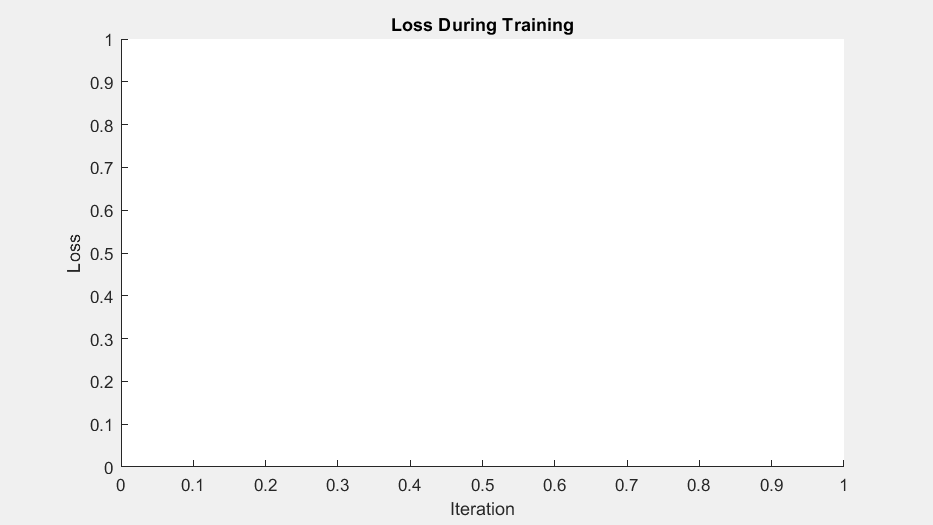

plotRatio = 16/9;

if plots == "training-progress"
    trainingPlot = figure;
    trainingPlot.Position(3) = plotRatio*trainingPlot.Position(4);
    trainingPlot.Visible = 'on';
    
    trainingPlotAxes = gca;
    
    lineLossTrain = animatedline(trainingPlotAxes);
    xlabel(trainingPlotAxes,"Iteration")
    ylabel(trainingPlotAxes,"Loss")
    title(trainingPlotAxes,"Loss During Training")
end

**Train Model**

Train the model using a custom training loop. Looping over the training data and update the network parameters at each iteration.

For each iteration:

- Extracting a batch of image pairs and labels using the `getSiameseBatch.`

- Converting the data to `dlarray` objects with underlying type `single` and specify the dimension labels `'SSCB'` (spatial, spatial, channel, batch) for the image data and `'CB'` (channel, batch) for the labels.

- Evaluating the model gradients using `dlfeval` and the `modelGradients` function.

- Updating the network parameters using the `adamupdate` function.

% Loop over mini-batches.
for iteration = 1:numIterations
    
    % Extract mini-batch of image pairs and pair labels
    [X1,X2,pairLabels] = getSiameseBatch(imdsTrain,miniBatchSize);
    
    % Convert mini-batch of data to dlarray. Specify the dimension labels
    % 'SSCB' (spatial, spatial, channel, batch) for image data
    dlX1 = dlarray(single(X1),'SSCB');
    dlX2 = dlarray(single(X2),'SSCB');
       
    % Evaluate the model gradients and the generator state using
    % dlfeval and the modelGradients function listed at the end of the
    % example.
    [gradientsSubnet, gradientsParams,loss] = dlfeval(@modelGradients,dlnet,fcParams,dlX1,dlX2,pairLabels);
    lossValue = double(gather(extractdata(loss)));
    
    % Update the Siamese subnetwork parameters.
    [dlnet,trailingAvgSubnet,trailingAvgSqSubnet] = adamupdate(dlnet,gradientsSubnet, ...
        trailingAvgSubnet,trailingAvgSqSubnet,iteration,learningRate,gradDecay,gradDecaySq);
    
    % Update the fullyconnect parameters.
    [fcParams,trailingAvgParams,trailingAvgSqParams] = adamupdate(fcParams,gradientsParams, ...
        trailingAvgParams,trailingAvgSqParams,iteration,learningRate,gradDecay,gradDecaySq);
      
    % Update the training loss progress plot.
    if plots == "training-progress"
        addpoints(lineLossTrain,iteration,lossValue);
    end
    drawnow;
    
    %Epoch
    disp("Epoch = "+int2str(iteration));
    
end

Unrecognized function or variable 'trailingAvgSubnet'.

Loading the test data as a image datastore using the `imageDatastore` function. Specifying the labels manually by extracting the labels from the file names and setting the `Labels` property.

imdsTest = imageDatastore("FaceData_Test", ...
    'IncludeSubfolders',true, ...
    'LabelSource','none');    

files = imdsTest.Files;
parts = split(files,filesep);
labels = join(parts(:,(end-2):(end-1)),'_');
imdsTest.Labels = categorical(labels);

The test dataset contains images of 8 persons that are different to those that the network was trained on. In total, there 8 different classes in the test dataset.

numClasses = numel(unique(imdsTest.Labels))

To calculate the accuracy of the network, creating a set of five random mini-batches of test pairs. Using the predictSiamese function to evaluate the network predictions and calculate the average accuracy over the mini-batches.

accuracy = zeros(1,5);
accuracyBatchSize = 16;

for i = 1:5
    
    % Extract mini-batch of image pairs and pair labels
    [XAcc1,XAcc2,pairLabelsAcc] = getSiameseBatch(imdsTest,accuracyBatchSize);
    
    % Convert mini-batch of data to dlarray. Specify the dimension labels
    % 'SSCB' (spatial, spatial, channel, batch) for image data.
    dlXAcc1 = dlarray(single(XAcc1),'SSCB');
    dlXAcc2 = dlarray(single(XAcc2),'SSCB');
         
    % Evaluate predictions using trained network
    dlY = predictSiamese(dlnet,fcParams,dlXAcc1,dlXAcc2);
   
    % Convert predictions to binary 0 or 1
    Y = gather(extractdata(dlY));
    Y = round(Y);
    
    % Compute average accuracye for the minibatch
    accuracy(i) = sum(Y == pairLabelsAcc)/accuracyBatchSize;
end

% Compute accuracy over all minibatches
averageAccuracy = mean(accuracy)*100

**Display a Test Set of Images with Predictions**

To visually check if the network correctly identifies similar and dissimilar pairs, creating a small batch of image pairs to test. Using the predictSiamese function to get the prediction for each test pair. Displaying the pair of images with the prediction, the probability score, and a label indicating whether the prediction was correct or incorrect.

testBatchSize = 10;

[XTest1,XTest2,pairLabelsTest] = getSiameseBatch(imdsTest,testBatchSize);
    
% Convert test batch of data to dlarray. Specify the dimension labels
% 'SSCB' (spatial, spatial, channel, batch) for image data and 'CB' 
% (channel, batch) for labels
dlXTest1 = dlarray(single(XTest1),'SSCB');
dlXTest2 = dlarray(single(XTest2),'SSCB');

% Calculate the predicted probability
dlYScore = predictSiamese(dlnet,fcParams,dlXTest1,dlXTest2);
YScore = gather(extractdata(dlYScore));

% Convert predictions to binary 0 or 1
YPred = round(YScore);    

% Extract data to plot
XTest1 = extractdata(dlXTest1);
XTest2 = extractdata(dlXTest2);

% Plot images with predicted label and predicted score
testingPlot = figure;
testingPlot.Position(3) = plotRatio*testingPlot.Position(4);
testingPlot.Visible = 'on';
    
for i = 1:numel(pairLabelsTest)
     
    if YPred(i) == 1
        predLabel = "Similar";
    else
        predLabel = "Dissimilar" ;
    end
    
    if pairLabelsTest(i) == YPred(i)
        testStr = "\bf\color{darkgreen}Correct\rm\newline";
        
    else
        testStr = "\bf\color{red}Incorrect\rm\newline";
    end
    
    photo1 = cast(XTest1(:,:,:,i), 'uint8');
    photo2 = cast(XTest2(:,:,:,i), 'uint8');
    
    subplot(2,5,i)        
    imshow([photo1 photo2]);        
    
    title(testStr + "\color{black}Predicted: " + predLabel + "\newlineScore: " + YScore(i)); 
end

The network is able to compare the test images to determine their similarity, even though none of these images were in the training dataset.